% Set up
clc;
close all;
clear;

## load data

## Re-organize data(eeg)

The data is set to m*n matrix

m = number of epochs

n = Frequency of Sampling * epoch length

test = 1

test = 1

EEG1 = []


EEG1 =

     []



EEG2 = []


EEG2 =

     []



STAGE = []


STAGE =

     []



% load test data
edfFilename = sprintf('R%d_edf.mat', test);
xmlFilename = sprintf('R%d_xml.mat', test);
load(edfFilename);
load(xmlFilename);
hdr.label

ans = 1×14 cell array
    {'SaO2'}    {'HR'}    {'EEGsec'}    {'ECG'}    {'EMG'}    {'EOGL'}    {'EOGR'}    {'EEG'}    {'THORRES'}    {'ABDORES'}    {'POSITION'}    {'LIGHT'}    {'NEWAIR'}    {'OXstat'}


% We can know from the hdr that the 3rd and the 8th 
% channel of the record is EEG signal
Fs = hdr.samples(3);
% every epoch lasts for epochLength seconds (30 seconds)
numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
% Initialization of eeg1 and eeg2
eeg1 = zeros(numberOfEpochs,Fs*epochLength);
eeg2 = zeros(numberOfEpochs,Fs*epochLength);
epochAmount = 1;    % How much epoches to cut for one row
for i = 1:numberOfEpochs
    epochNumber = i;    % start epoch No.
    epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
    epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
    t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
    eeg1(i,:) = record(8,epochStart:epochEnd);
    eeg2(i,:) = record(3,epochStart:epochEnd);
end
EEG1_test = eeg1;
EEG2_test = eeg2;
% process the stages
stages_epoch = zeros(1,numberOfEpochs);
for i = 1:numberOfEpochs
    stages_epoch(i) = stages(i*30);
end
STAGE_test = stages_epoch;

train = 1:10;
train(train == test) = [];
% load train data
for n = train
    edfFilename = sprintf('R%d_edf.mat', n);
    xmlFilename = sprintf('R%d_xml.mat', n);
    load(edfFilename);
    load(xmlFilename);

    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
    end
    EEG1 = [EEG1;eeg1];
    EEG2 = [EEG2;eeg2];
    % process the stages
    stages_epoch = zeros(1,numberOfEpochs);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE = [STAGE,stages_epoch];
end

## Plot for check

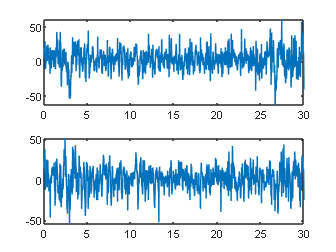

% Plot the first epoch
figure(1)
subplot(2,1,1)
plot(t,EEG1(1,:))
subplot(2,1,2)
plot(t,EEG2(1,:))


% FFT to see frequency domain
% N = 1024;
% EEG1 = abs(fftshift(fft(eeg1(1,:),N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1)

## Remove the baseline drift

% It will filter every row
EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

EEG1_test_filtered = baseline_drift_removal(EEG1_test,Fs,0.5);
EEG2_test_filtered = baseline_drift_removal(EEG2_test,Fs,0.5);

## Muscle noise filtering & Power line interference removal

EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

EEG1_test_filtered = muscle_noise_filtering(EEG1_test_filtered,Fs,30);
EEG2_test_filtered = muscle_noise_filtering(EEG2_test_filtered,Fs,30);

## Check changes in frequency domain

% FFT
% N = 1024;
% EEG1_F = abs(fftshift(fft(eeg1_filtered,N)));
% fshift=linspace(-0.5*Fs,0.5*Fs,N);     % fftshift x axis
% figure;
% plot(fshift,EEG1,fshift,EEG1_F)

## Feature Extraction - Time-domain

features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);

features_time_eeg1_test = extract_time_features(EEG1_test_filtered);
features_time_eeg2_test = extract_time_features(EEG2_test_filtered);


feature_labels = {'Mean', 'Variance', 'Skewness', 'Kurtosis', ...
                  'Zero-Crossing Rate', 'Hjorth Activity', ...
                  'Hjorth Mobility', 'Hjorth Complexity'};

disp('Characteristics of EEG1 (Time-Domain):');

Characteristics of EEG1 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg1(i));
end

Mean: 0.0210
Variance: 0.1810
Skewness: -0.2066
Kurtosis: 0.0449
Zero-Crossing Rate: -0.0313
Hjorth Activity: -0.0355
Hjorth Mobility: 0.0293
Hjorth Complexity: -0.1628



disp('Characteristics of EEG2 (Time-Domain):');

Characteristics of EEG2 (Time-Domain):


for i = 1:length(feature_labels)
    fprintf('%s: %.4f\n', feature_labels{i}, features_time_eeg2(i));
end

Mean: 0.0262
Variance: 0.0159
Skewness: -0.0881
Kurtosis: -0.0394
Zero-Crossing Rate: -0.2019
Hjorth Activity: -0.0408
Hjorth Mobility: 0.0099
Hjorth Complexity: -0.1252


## Feature Extraction - Frequency Domain

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

[features_freq_eeg1_test, Pxx_eeg1_test, freqs_eeg1_test] = extract_freq_features(EEG1_test_filtered, Fs);
[features_freq_eeg2_test, Pxx_eeg2_test, freqs_eeg2_test] = extract_freq_features(EEG2_test_filtered, Fs);

feature_labels_freq = {'Power Delta', 'Power Theta', 'Power Alpha', 'Power Beta', 'Power Gamma', ...
                      'Spectral Edge Frequency', ...
                      'Relative Delta', 'Relative Theta', 'Relative Alpha', 'Relative Beta', 'Relative Gamma'};

disp('Characteristics of EEG1 (Frequency-Domain):');

Characteristics of EEG1 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg1(i));
end

Power Delta: 6777.4693
Power Theta: 11229.3600
Power Alpha: 6513.6253
Power Beta: 9211.2052
Power Gamma: 11123.9064
Spectral Edge Frequency: 9768.1778
Relative Delta: 11233.6962
Relative Theta: 5817.6840
Relative Alpha: 9474.2615
Relative Beta: 3117.6757
Relative Gamma: 5575.2584



disp('Characteristics of EEG2 (Frequency-Domain):');

Characteristics of EEG2 (Frequency-Domain):


for i = 1:length(feature_labels_freq)
    fprintf('%s: %.4f\n', feature_labels_freq{i}, features_freq_eeg2(i));
end

Power Delta: 6800.7709
Power Theta: 11995.7519
Power Alpha: 9237.0458
Power Beta: 9757.0650
Power Gamma: 10851.7076
Spectral Edge Frequency: 6514.8886
Relative Delta: 13328.4631
Relative Theta: 4860.2425
Relative Alpha: 10289.2710
Relative Beta: 4212.5765
Relative Gamma: 4973.0364


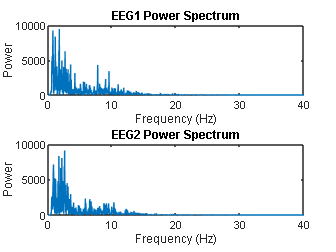


figure;
subplot(2,1,1);
plot(freqs_eeg1, Pxx_eeg1(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG1 Power Spectrum');
xlim([0 40]);

subplot(2,1,2);
plot(freqs_eeg2, Pxx_eeg2(1,:));
xlabel('Frequency (Hz)');
ylabel('Power');
title('EEG2 Power Spectrum');
xlim([0 40]);

## Time Frequency

% Extract time-frequency features
features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);

features_timefreq_eeg1_test = extract_timefreq_features(EEG1_test_filtered, Fs);
features_timefreq_eeg2_test = extract_timefreq_features(EEG2_test_filtered, Fs);

% Append the new features to the existing feature set
features = [features_time_eeg1, features_freq_eeg1, features_timefreq_eeg1];
features_test = [features_time_eeg1_test, features_freq_eeg1_test, features_timefreq_eeg1_test];

% Display extracted features
disp('Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):');

Time-Frequency Features for EEG1 (Wavelet Energy & Spectral Entropy):


disp(features_timefreq_eeg1);  

   1.0e+05 *

    0.0155    0.0001
    0.0155    0.0001
    0.0149    0.0001
    0.0144    0.0001
    0.0136    0.0001
    0.0195    0.0001
    0.0290    0.0001
    0.0273    0.0001
    0.1121    0.0001
    0.0164    0.0001
    0.0169    0.0001
    0.0181    0.0001
    0.0184    0.0001
    0.0161    0.0001
    0.0155    0.0001
    0.0148    0.0001
    0.0147    0.0001
    0.0150    0.0001
    0.0144    0.0001
    0.0127    0.0001
    0.0138    0.0001
    0.0132    0.0001
    0.0138    0.0001
    0.0193    0.0001
    0.0166    0.0001
    0.0127    0.0001
    0.0148    0.0001
    0.0144    0.0001
    0.0146    0.0001
    0.0131    0.0001
    0.0135    0.0001
    0.0128    0.0001
    0.0124    0.0001
    0.0129    0.0001
    0.0123    0.0001
    0.0114    0.0001
    0.0905    0.0001
    0.0139    0.0001
    0.0142    0.0001
    0.0134    0.0001
    0.0130    0.0001
    0.0116    0.0001
    0.0126    0.0001
    0.0125    0.0001
    0.0177    0.0001
    0.0116    0.0001
    0.0120    0.0001


disp('Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):');

Time-Frequency Features for EEG2 (Wavelet Energy & Spectral Entropy):


disp(features_timefreq_eeg2);  

   1.0e+05 *

    0.0134    0.0001
    0.0166    0.0001
    0.0130    0.0001
    0.0138    0.0001
    0.0135    0.0001
    0.0185    0.0001
    0.0193    0.0001
    0.0169    0.0001
    0.0311    0.0001
    0.0159    0.0001
    0.0177    0.0001
    0.0159    0.0001
    0.0166    0.0001
    0.0151    0.0001
    0.0135    0.0001
    0.0138    0.0001
    0.0128    0.0001
    0.0139    0.0001
    0.0140    0.0001
    0.0123    0.0001
    0.0121    0.0001
    0.0114    0.0001
    0.0122    0.0001
    0.0125    0.0001
    0.0125    0.0001
    0.0110    0.0001
    0.0135    0.0001
    0.0139    0.0001
    0.0127    0.0001
    0.0128    0.0001
    0.0113    0.0001
    0.0119    0.0001
    0.0122    0.0001
    0.0116    0.0001
    0.0108    0.0001
    0.0103    0.0001
    0.0252    0.0001
    0.0120    0.0001
    0.0122    0.0001
    0.0100    0.0001
    0.0107    0.0001
    0.0100    0.0001
    0.0101    0.0001
    0.0101    0.0001
    0.0125    0.0001
    0.0105    0.0001
    0.0095    0.0001


disp('Time-Frequency Features for EEG1 (Test Data):');

Time-Frequency Features for EEG1 (Test Data):


disp(features_timefreq_eeg1_test);  

   1.0e+05 *

    1.2194    0.0001
    0.6570    0.0001
    0.7742    0.0001
    0.5130    0.0001
    0.7378    0.0001
    0.5322    0.0001
    0.7514    0.0001
    0.6334    0.0001
    0.4784    0.0001
    0.5863    0.0001
    0.5059    0.0001
    0.5863    0.0001
    1.0937    0.0001
    0.5709    0.0001
    0.8539    0.0001
    0.8758    0.0001
    0.8285    0.0001
    1.0621    0.0001
    0.8390    0.0001
    1.0624    0.0001
    1.1966    0.0001
    0.6993    0.0001
    0.8834    0.0001
    1.2451    0.0001
    0.3807    0.0001
    0.4204    0.0001
    0.7658    0.0001
    0.0625    0.0001
    0.0334    0.0001
    0.0230    0.0001
    0.0271    0.0001
    0.4864    0.0001
    0.1422    0.0001
    0.0322    0.0001
    0.0244    0.0001
    0.0241    0.0001
    0.0229    0.0001
    0.0245    0.0001
    0.0230    0.0001
    0.0241    0.0001
    0.0198    0.0001
    0.0216    0.0001
    0.0206    0.0001
    0.0195    0.0001
    0.0166    0.0001
    0.0178    0.0001
    0.0190    0.0001


disp('Time-Frequency Features for EEG2 (Test Data):');

Time-Frequency Features for EEG2 (Test Data):


disp(features_timefreq_eeg2_test);  

   1.0e+05 *

    0.2596    0.0001
    0.2090    0.0001
    0.5629    0.0001
    0.2498    0.0001
    0.8051    0.0001
    0.4453    0.0001
    0.3881    0.0001
    0.2599    0.0001
    0.1625    0.0001
    0.3329    0.0001
    0.2445    0.0001
    0.2558    0.0001
    0.6691    0.0001
    0.3502    0.0001
    0.2544    0.0001
    0.1435    0.0001
    0.2567    0.0001
    0.1931    0.0001
    0.1816    0.0001
    0.3349    0.0001
    0.3141    0.0001
    0.1517    0.0001
    0.2973    0.0001
    0.3530    0.0001
    0.2268    0.0001
    0.1165    0.0001
    0.1037    0.0001
    0.0388    0.0001
    0.0212    0.0001
    0.0169    0.0001
    0.0184    0.0001
    0.2002    0.0001
    0.0404    0.0001
    0.0196    0.0001
    0.0170    0.0001
    0.0169    0.0001
    0.0175    0.0001
    0.0167    0.0001
    0.0154    0.0001
    0.0160    0.0001
    0.0136    0.0001
    0.0145    0.0001
    0.0152    0.0001
    0.0143    0.0001
    0.0118    0.0001
    0.0133    0.0001
    0.0114    0.0001

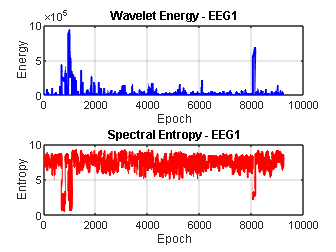


% Plot extracted features for EEG1
figure;

subplot(2,1,1);
plot(features_timefreq_eeg1(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG1');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg1(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG1');
ylabel('Entropy');
xlabel('Epoch');
grid on;

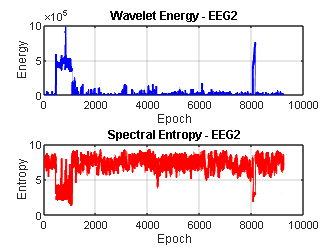


set(gcf, 'color', 'w'); % Set background color to white

% Plot extracted features for EEG2
figure;

subplot(2,1,1);
plot(features_timefreq_eeg2(:,1), 'b', 'LineWidth', 1.5); 
title('Wavelet Energy - EEG2');
ylabel('Energy');
xlabel('Epoch');
grid on;

subplot(2,1,2);
plot(features_timefreq_eeg2(:,2), 'r', 'LineWidth', 1.5); 
title('Spectral Entropy - EEG2');
ylabel('Entropy');
xlabel('Epoch');
grid on;


set(gcf, 'color', 'w'); % Set background color to white



## Classification

features = [features_time_eeg1, features_freq_eeg1];
features = normalize(features);
size(features)

ans =         9210          19


labels = categorical(STAGE, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});
size(labels)

ans =            1        9210



features_test = [features_time_eeg1_test, features_freq_eeg1_test];
features_test = normalize(features_test)

features_test =     0.6195   -0.2829   -0.6148    0.0530    2.4130   -0.2829    2.4892   -1.1998   -0.2370   -0.3028    0.1512   -0.2445    3.8817    2.8870   -1.2500   -1.0430    0.0680    1.2772    3.9739
    0.0438   -0.4052   -1.1172   -0.2002    2.6720   -0.4052    2.6722   -1.3006   -0.3527   -0.3731   -0.4000   -0.3218    2.1756    2.7996   -1.6074   -0.6276   -0.2837    1.5625    4.9863
   -0.2422   -0.2601   -3.3507    0.6953    1.8240   -0.2601    1.4039   -0.7417   -0.0651   -0.2596    0.0047   -0.2959    1.5599    2.0269   -0.2608   -0.9669   -0.3476    0.5030    1.4178
   -0.0133   -0.4095   -0.9018    0.0382    2.3775   -0.4095    2.1588   -1.0652   -0.3123   -0.4000   -0.3250   -0.3488    1.2171    2.5981   -0.9685   -0.8041    0.0802    0.9809    3.2008
    0.4894   -0.2147   -2.6761    1.4442    1.8240   -0.2147    1.0567   -0.5328    0.0415   -0.2686    0.3760   -0.3050    2.3091    1.5230    0.0115   -1.1511    0.0203    0.2169    1.7429
   -0.6790   -0.4053   -2.349

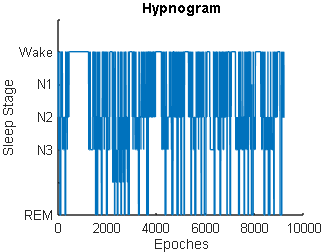

labels_test = categorical(STAGE_test, [0 1 2 3 4 5], {'REM', 'None', 'N3', 'N2', 'N1', 'Wake'});

figure;
plot(STAGE); %sleep stages are for 30 seconds epochs
ylim([0 6]);
set(gca,'ytick',0:6,'yticklabel',{'REM','','N3','N2','N1','Wake',''});
xlabel('Epoches');
ylabel('Sleep Stage');
box off;
title('Hypnogram');

set(gcf,'color','w');
